% Define the number of simulation steps
num_steps = 20;


axis_vec = [1; 0; 0];
axis_unit_vec = axis_vec/norm(axis_vec);
theta_disp = 50; % in degrees
q_body = [sin(theta_disp/2 * pi/180) * axis_unit_vec; cos(theta_disp/2 * pi/180)];
A_start = attitude_matrix(q_body);
% Generate example data for the ECI frame (assuming these are constant for simplicity)
sun_vec_eci = repmat([1; 0; 0.0], 1, num_steps);
mag_vec_eci = repmat([0.1234; 0.4567; 0.7890], 1, num_steps);

% Generate example data for the body frame with some added noise
rng(0); % For reproducibility
sun_vec_body = repmat(A_start * [1; 0; 0], 1, num_steps) + 0.01 * randn(3, num_steps);
mag_vec_body = repmat(A_start * [0.1234; 0.4567; 0.7890], 1, num_steps) + 0.01 * randn(3, num_steps);


% Initial measurements vector (concatenation of sun and magnetic field vectors in the body frame)
zk_array = [sun_vec_body; mag_vec_body];

% Angular velocity measurements (assume some constant rotation with noise)
omega_meas = repmat([0.01; 0.01; 0.01], 1, num_steps) + 0.0001 * randn(3, num_steps);

std_dev_sun_vec = [0.001; 0.001; 0.001];

std_dev_magnet = [0.01; 0.01; 0.01];

% Initialize MEKF parameters
R_input = [diag(std_dev_sun_vec)^2, zeros(3,3); zeros(3,3), diag(std_dev_magnet)^2]; % State covariance matrix
Q_start = 0.000001 * eye(6); % Process covariance matrix
P_start = 0.1 * eye(6); % Initial state covariance matrix
x_init = [0; 0; 0; 0.001; 0.001; 0.001]; % Initial state vector
dt = 0.1; % Time step

std_dev_biases = [0.0001; 0.0001; 0.0001; 0.00001; 0.00001; 0.00001];
% Create MEKF object
mekf = MEKF(R_input, P_start, x_init, dt, std_dev_biases);





meas_std_dev = diag([std_dev_sun_vec; std_dev_magnet]);

% Arrays to store results
q_est_array = zeros(4, num_steps);
x_est_array = zeros(6, num_steps);
q_actual_array = zeros(4, num_steps);

% Initialize reference quaternion (actual quaternion)
q_actual = [0; 0; 0; 1]; % Assuming [q1; q2; q3; q4] convention

b_meas_first = mag_vec_body( : ,1);
sun_meas_first = sun_vec_body(:, 1);

b_prop_first = mag_vec_eci( : ,1);
sun_prop_first = sun_vec_eci(:, 1);

v1 = b_prop_first;
v1 = v1/norm(v1);
v2 = cross(v1, sun_prop_first);
v2 = v2/norm(v2);
v3 = cross(v1, v2);
V = [v1, v2, v3];


w1 = b_meas_first;
w1 = w1/norm(w1);
w2 = cross(w1, sun_meas_first);
w2 = w2/norm(w2);
w3 = cross(w1, w2);
W = [w1, w2, w3];

A_start = W * V'

A_start =     0.9996   -0.0279    0.0024
    0.0163    0.6496    0.7601
   -0.0228   -0.7598    0.6498


q_start = quaternion_from_attitude(A_start);

disp(q_start);

   -0.4184
    0.0070
    0.0122
    0.9081



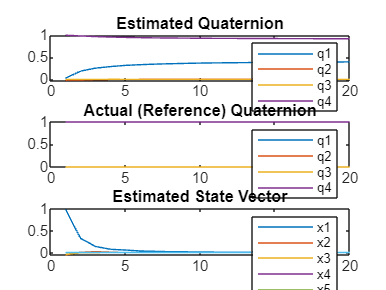


mekf.q_prop = q_start;
mekf.q_est = q_start;
mekf.q_ref = q_start;

% Run the simulation
for k = 1:num_steps
    % Perform state prediction
    mekf = mekf.predict_state(omega_meas(:, k));
    
    % Perform measurement update
    mekf = mekf.measurement_update(zk_array(:, k), sun_vec_eci(:, k), mag_vec_eci(:, k));
    
    % Store the estimated quaternion and state vector
    q_est_array(:, k) = mekf.q_est;
    x_est_array(:, k) = mekf.x_prop;
    
    % Store the actual quaternion (reference quaternion)
    q_actual_array(:, k) = q_actual;
    
    % Perform reset (assuming it's done at each step)
    
    mekf = mekf.reset();

end

% Plot the results
figure;
subplot(3, 1, 1);
plot(1:num_steps, q_est_array);
title('Estimated Quaternion');
legend('q1', 'q2', 'q3', 'q4');

subplot(3, 1, 2);
plot(1:num_steps, q_actual_array);
title('Actual (Reference) Quaternion');
legend('q1', 'q2', 'q3', 'q4');

subplot(3, 1, 3);
plot(1:num_steps, x_est_array);
title('Estimated State Vector');
legend('x1', 'x2', 'x3', 'x4', 'x5', 'x6');


% disp(attitude_matrix(mekf.q_est));
sun_est = attitude_matrix(mekf.q_est) * sun_vec_eci(:,num_steps);

disp('q_body');

q_body


disp(q_body);

    0.4226
         0
         0
    0.9063



disp('q_est');

q_est


disp(mekf.q_est);

    0.3953
    0.0008
    0.0003
    0.9186




function a = attitude_matrix(q)
    % Returns the attitude matrix of transformation from inertial to body
    % frame

    % Extract the components of the quaternion
    q1 = q(1);
    q2 = q(2);
    q3 = q(3);
    q4 = q(4); % q4 is the scalar component
    
    % Calculate the elements of the attitude (rotation) matrix
    a = [
        1 - 2*(q2^2 + q3^2), 2*(q1*q2 + q3*q4), 2*(q1*q3 - q2*q4);
        2*(q1*q2 - q3*q4), 1 - 2*(q1^2 + q3^2), 2*(q2*q3 + q1*q4);
        2*(q1*q3 + q2*q4), 2*(q2*q3 - q1*q4), 1 - 2*(q1^2 + q2^2)
    ];
end
function q = quaternion_from_attitude(A)
    % This function converts a rotation matrix A into a quaternion q
    % A is a 3x3 rotation matrix
    % q is a 1x4 quaternion [q1, q2, q3, q4] where q4 is the scalar part
    
    % Ensure the matrix is 3x3
    assert(all(size(A) == [3 3]), 'Input matrix must be 3x3');
    
    % Calculate the trace of the matrix
    traceA = trace(A);
    
    if traceA > 0
        % When the trace is positive
        S = sqrt(traceA + 1.0) * 2; % S = 4 * q4
        q4 = 0.25 * S;
        q1 = (A(3, 2) - A(2, 3)) / S;
        q2 = (A(1, 3) - A(3, 1)) / S;
        q3 = (A(2, 1) - A(1, 2)) / S;
    elseif (A(1, 1) > A(2, 2)) && (A(1, 1) > A(3, 3))
        % Column 1 has the greatest value
        S = sqrt(1.0 + A(1, 1) - A(2, 2) - A(3, 3)) * 2; % S = 4 * q1
        q4 = (A(3, 2) - A(2, 3)) / S;
        q1 = 0.25 * S;
        q2 = (A(1, 2) + A(2, 1)) / S;
        q3 = (A(1, 3) + A(3, 1)) / S;
    elseif A(2, 2) > A(3, 3)
        % Column 2 has the greatest value
        S = sqrt(1.0 + A(2, 2) - A(1, 1) - A(3, 3)) * 2; % S = 4 * q2
        q4 = (A(1, 3) - A(3, 1)) / S;
        q1 = (A(1, 2) + A(2, 1)) / S;
        q2 = 0.25 * S;
        q3 = (A(2, 3) + A(3, 2)) / S;
    else
        % Column 3 has the greatest value
        S = sqrt(1.0 + A(3, 3) - A(1, 1) - A(2, 2)) * 2; % S = 4 * q3
        q4 = (A(2, 1) - A(1, 2)) / S;
        q1 = (A(1, 3) + A(3, 1)) / S;
        q2 = (A(2, 3) + A(3, 2)) / S;
        q3 = 0.25 * S;
    end
    
    % Combine into a quaternion with the scalar part as the last component
    q = [q1; q2; q3; q4];
    
end
